# Histogram-Based Entropy Estimation

This script introduces basic histogram methods for calculating entropy of continuous and discrete probability distributions.

## Initialize Workspace

% Clear everything:
clear all; close all force; clc;

% Path maintenance:
restoredefaultpath
addpath('matlab_tools')
addpath('project_tools')

% Initialize plotting tools:
fignum = 0;
colors = grab_plot_colors;

## Step 1: Create a Synthetic Mixture Density

% These exercises use synthetic data to explore relationships between:
%     (i) the generating probability mass function (PMF),
%    (ii) sample size, 
%   (iii) accuracy of resulting entropy estimators.
%
% We will use mixture densities with different kernels to generate
% semi-random distributions.

% How many kernels?
nKernels = 1;

% Which type(s) of kernel to use?
kernelType = 'Normal';

% Create a mixture density 'object':
mixtureDensity = create_mixture_density(nKernels,kernelType);

% Screen report:
fprintf('Creating a mixture density with %d %s kernel(s) ...',nKernels,kernelType);

Creating a mixture density with 1 Normal kernel(s) ...

## Step 1.1: Plot Synthetic Mixture Density

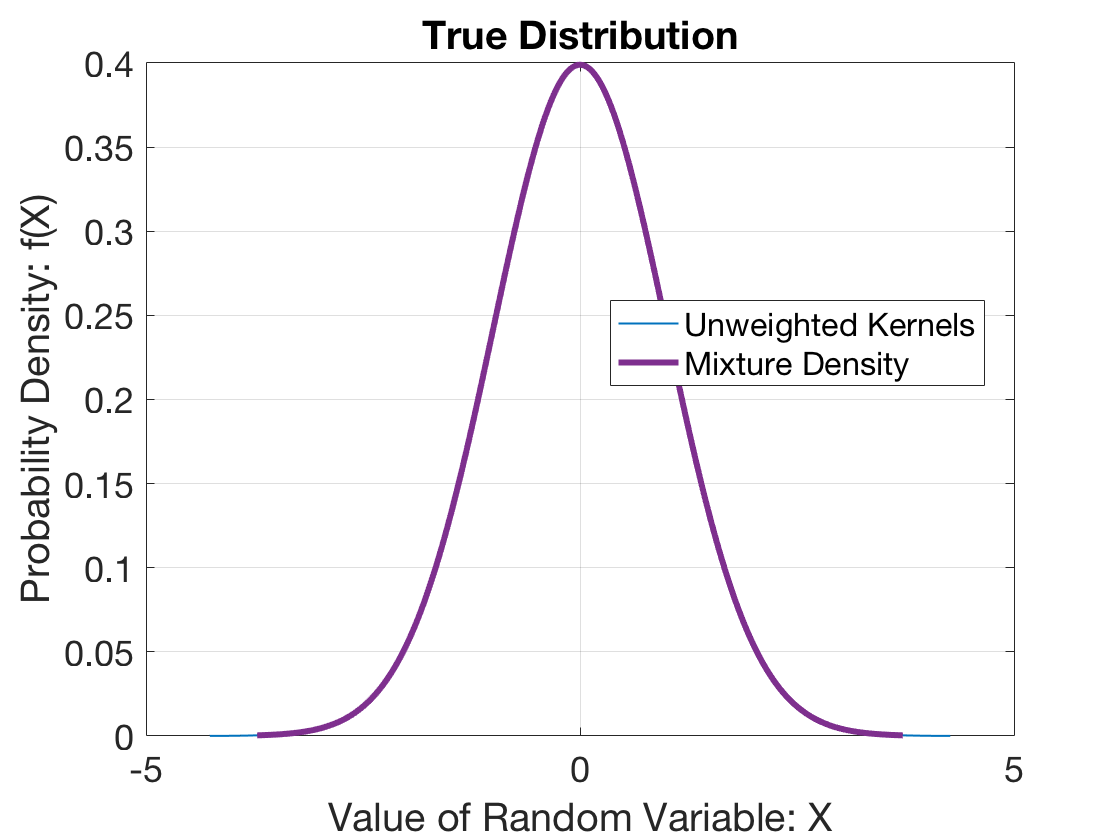

% Initialize a figure for plotting the mixture density:
fignum = fignum+1; figure(fignum); close(fignum); figure(fignum);

% Plot each kernel:
for k = 1:nKernels
    [Xkernel,Ykernel] = plot_kernel_density(mixtureDensity,k);
    kfig = plot(Xkernel,Ykernel,'color',colors(1,:),'linewidth',1);
    hold on;
    %     fprintf('Integral of kerenel #%d (%s) \t as plotted = %f\n',...
    %         k,mixtureDensity.kernels{k},sum(Ykernel .* diff(Xkernel(1:2))));
end

% Plot theoretical mixture density:
[Xtheoretical,Ytheoretical] = plot_mixture_density(mixtureDensity);
mfig = plot(Xtheoretical,Ytheoretical,'color',colors(4,:),'linewidth',3);

% labels & legend
legend([kfig,mfig],'Unweighted Kernels','Mixture Density','location','best');
ylabel('Probability Density: f(X)','fontsize',18);
xlabel('Value of Random Variable: X','fontsize',18);
title('True Distribution','fontsize',24)

% plotting aesthetics
set(gca,'fontsize',18);
grid on;

## Step 2: Calculate True Differential Entropy of the Mixture Density

% Entropy Definition: h = -integral{p(x) * ln[p(x)], dx}
% We will calculate this exactly from analytical integration.

% Only do this if there is a single kernel:
if nKernels == 1
    switch mixtureDensity.kernels{1}
        case 'Uniform'
            hTrueNats = log(mixtureDensity.params{1}(2) - mixtureDensity.params{1}(1));
            hTrueBits = log2(mixtureDensity.params{1}(2) - mixtureDensity.params{1}(1));
        case 'Exponential'
            hTrueNats = 1 - log(mixtureDensity.params{1}(1));
            hTrueBits = 1 - log2(mixtureDensity.params{1}(2));
        case 'Normal'
            hTrueNats = 1/2 * log(2*pi*exp(1)*mixtureDensity.params{1}(2)^2);
            hTrueBits = 1/2 * log2(2*pi*exp(1)*mixtureDensity.params{1}(2)^2);
    end
    
    % Screen report:
    fprintf(['Differential entropy of the continuous sampling distribution is: \n'...
        '---- h = %f [nats] \n' ...
        '---- h = %f [bits] \n'], ...
        hTrueNats,hTrueBits);
end

Differential entropy of the continuous sampling distribution is: 
---- h = 1.418939 [nats] 
---- h = 2.047096 [bits] 


## Step 3: Sample and Plot

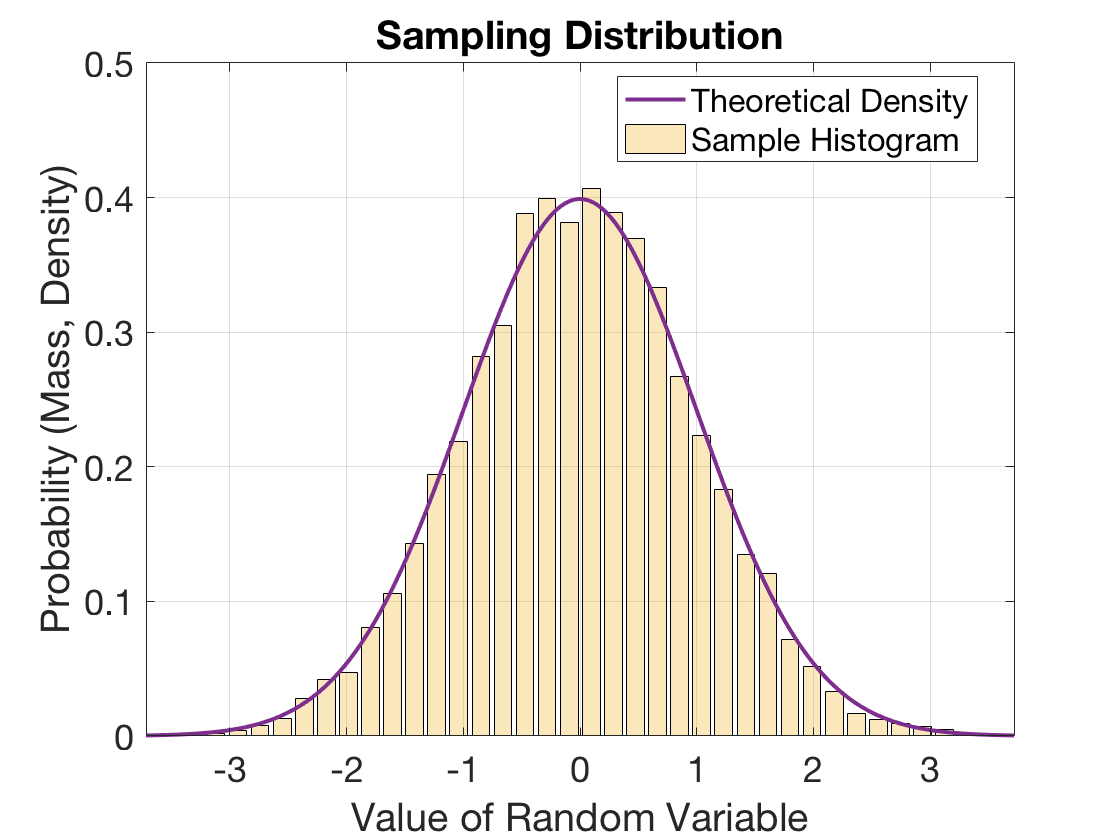

% How many samples?
logSamples = 4;
nSamples = round(10^logSamples);

% How many histogram bins?
nBins = 40;

% Sample the mixture density:
sample = sample_mixture_density(mixtureDensity,nSamples);

% Discretize the sample:
[histCounts,histEdges] = hist1(sample,nBins);   % this is a custom function
binWidth = histEdges(2) - histEdges(1);         % get bin width
histProbs = histCounts / nSamples;              % histogram counts -> probability mass
histDensities = histProbs / binWidth;           % probability mass -> probability density

% Initialize a figure for plotting the sample histogram:
fignum = fignum+1; figure(fignum); close(fignum); figure(fignum);

% Plot sample histogram:
histCenters = histEdges(2:end) - 1/2*binWidth;
sfig = bar(histCenters,histDensities,'facecolor',colors(3,:),'facealpha',0.3);
hold on;

% Plot theoretical mixture density:
[Xtheoretical,Ytheoretical] = plot_mixture_density(mixtureDensity);
mfig = plot(Xtheoretical,Ytheoretical,'color',colors(4,:),'linewidth',2);

% Labels & legend:
legend([mfig,sfig],'Theoretical Density','Sample Histogram','location','best');
ylabel('Probability (Mass, Density)','fontsize',18);
xlabel('Value of Random Variable','fontsize',18);
title('Sampling Distribution','fontsize',24);

% Plotting aesthetics:
set(gca,'fontsize',18);
grid on;
set(gca,'xlim',[Xtheoretical(1),Xtheoretical(end)]);

## Step 4: Estimate Discrete Entropy

% Entropy Definition: H = -sum{i}{p(xi) * ln[p(xi)]}

% Calculate discrete entropy:
iNonZero = find(histCounts>0);
hDiscreteNats = -histProbs(iNonZero)' * log(histProbs(iNonZero));
hDiscreteBits = -histProbs(iNonZero)' * log2(histProbs(iNonZero));

% Screen report:
fprintf(['Discrete entropy estimated over %d bins with %d samples is: \n'...
    '---- H = %f [nats] \n' ...
    '---- H = %f [bits] \n'], ...
    nBins,nSamples,hDiscreteNats,hDiscreteBits);

Discrete entropy estimated over 40 bins with 10000 samples is: 
---- H = 3.069311 [nats] 
---- H = 4.428079 [bits] 


## Step 5: Estimate Differential Entropy

% Entropy Definition: h = -integral{p(x) * ln[p(x)], dx}

% Calculate a numerical approximation of differential entropy:
iNonZero = find(histCounts>0);
hDifferentialNats = -histProbs(iNonZero)' * log(histDensities(iNonZero));
hDifferentialBits = -histProbs(iNonZero)' * log2(histDensities(iNonZero));

% Screen report:
fprintf(['Differential entropy estimated using %d bins with %d samples is: \n'...
    '---- h = %f [nats] \n' ...
    '---- h = %f [bits] \n'], ...
    nBins,nSamples,hDifferentialNats,hDifferentialBits);

Differential entropy estimated using 40 bins with 10000 samples is: 
---- h = 1.404399 [nats] 
---- h = 2.026120 [bits] 


## Step 6: Effects of Sample Size, Bin Width, and Number of Bins

% Increasing sample size:
nSampleSizes = 15;
sampleSizes = unique(round(logspace(1,5,nSampleSizes)));

% Increasing number of histogram bins:
nBinCounts = 15;
binCounts = unique(round(logspace(1,3,nBinCounts)));

% Number of resampling experiments:
nResamples =5;

% Initialize storage:
hDiscreteConvergence = zeros(nSampleSizes,nBinCounts,nResamples)./0;
hDifferentialConvergence = zeros(nSampleSizes,nBinCounts,nResamples)./0;

% Loop through resampling experiments:
for r = 1:nResamples
    
    % Initialize progress bar:
    totalCalcs = nSampleSizes * nBinCounts;
    timerCalcs = round(linspace(1,totalCalcs,50));
    calcCount = 0;
    tic;
    
    % Screen report:
    fprintf('Sample #%d of %d ... \n',r,nResamples);
    fprintf(strcat(repmat('.',[1,50]),'\n'));
    
    % Draw one master sample from the mixture density:
    resample = sample_mixture_density(mixtureDensity,sampleSizes(end));
    
    % Loop through sample sizes and bin counts:
    for s = 1:nSampleSizes
        for c = 1:nBinCounts
            
            % Screen report:
            calcCount = calcCount + 1;
            if ismember(calcCount,timerCalcs)
                fprintf('.');
            end
            
            % random permutation of the master sample:
            iSamp = randperm(sampleSizes(end),sampleSizes(s));
            
            % Discretize the sample:
            [histCounts,histEdges] = hist1(resample(iSamp),binCounts(c));
            histProbs = histCounts / sampleSizes(s);
            histDensities = histProbs / (histEdges(2) - histEdges(1));
            iNonZero = find(histCounts>0);
            
            % Calculate discrete entropy:
            hDiscreteConvergence(s,c,r) = -histProbs(iNonZero)' * log(histProbs(iNonZero));
            
            % Calculate a numerical approximation of differential entropy:
            hDifferentialConvergence(s,c,r) = -histProbs(iNonZero)' * log(histDensities(iNonZero));
            
        end % c-loop
    end % s-loop
    
    % Screent report:
    fprintf('time = %f[s] \n\n',toc);
    
end % r-loop

Sample #1 of 5 ... 


..................................................


..................................................

time = 4.148347[s] 



Sample #2 of 5 ... 


..................................................


..................................................

time = 5.447655[s] 



Sample #3 of 5 ... 


..................................................


..................................................

time = 5.541237[s] 



Sample #4 of 5 ... 


..................................................


..................................................

time = 4.973056[s] 



Sample #5 of 5 ... 


..................................................


..................................................

time = 5.102874[s] 



## Step 6.1: Plot Convergence Estimates

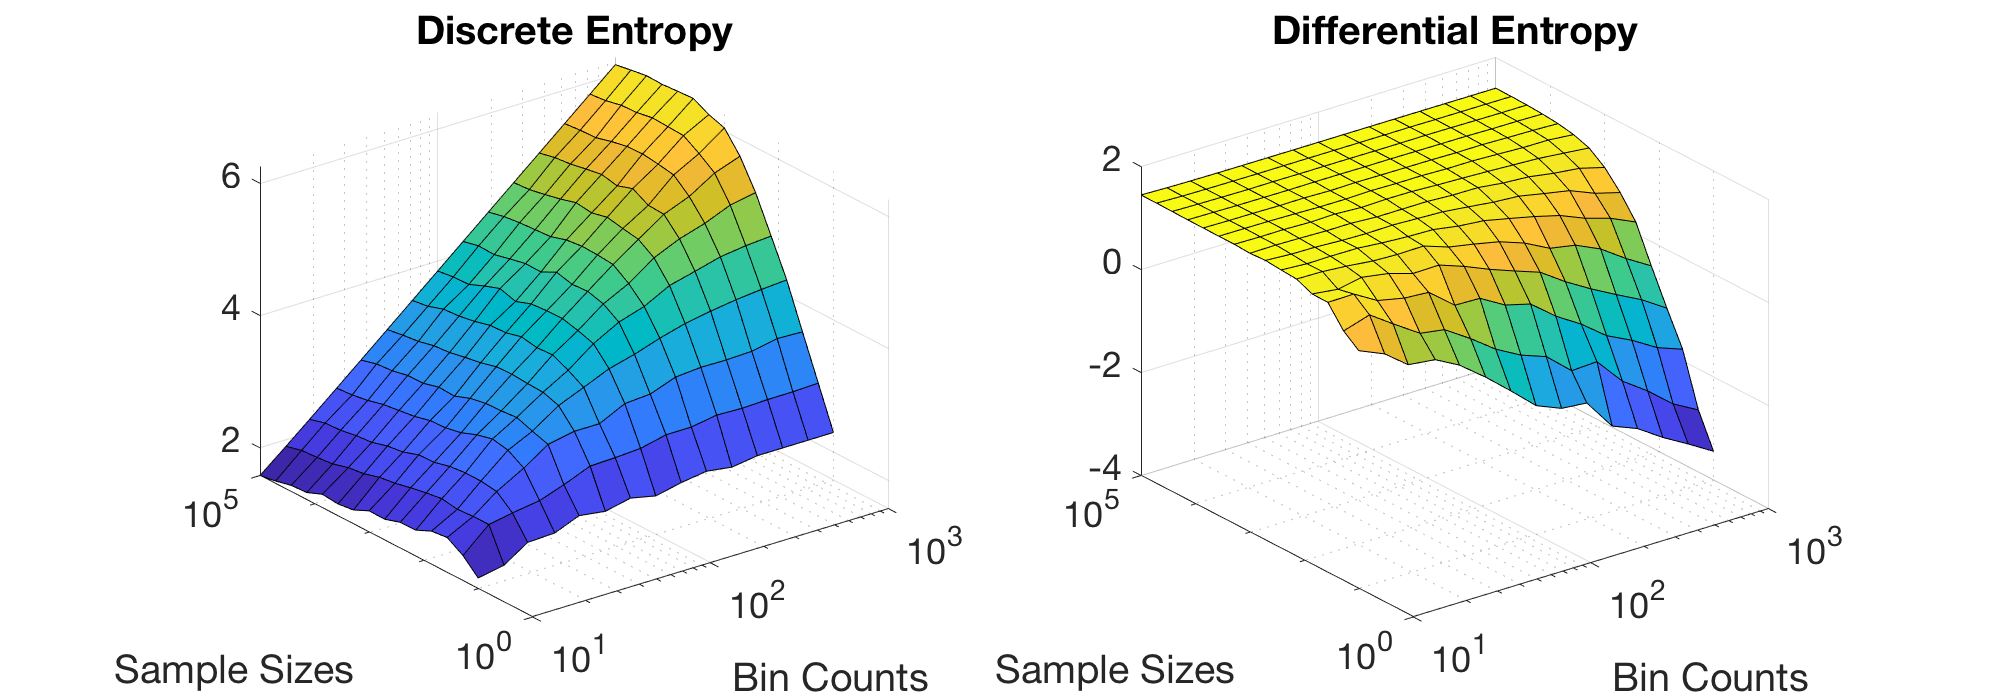

% Initialize a figure for plotting entropy estimates:
fignum = fignum+1; figure(fignum); close(fignum); figure(fignum);
set(gcf,'position',[1,1,1000,350])

% Plot discrete entropies:
subplot(1,2,1)
surf(binCounts,sampleSizes,mean(hDiscreteConvergence,3));

% Aesthetics:
set(gca,'Xscale','log','Yscale','log')
xlabel('Bin Counts')
ylabel('Sample Sizes')
title('Discrete Entropy')
set(gca,'fontsize',18);
grid on;

% Plot differential entropies:
subplot(1,2,2)
surf(binCounts,sampleSizes,mean(hDifferentialConvergence,3));

% Aesthetics:
set(gca,'Xscale','log','Yscale','log')
xlabel('Bin Counts')
ylabel('Sample Sizes')
title('Differential Entropy')
set(gca,'fontsize',18);
grid on;